% Wildtype example unit + trace
spikeTimes_samples = all_data.Wildtype.wt_exp1.cid706.SpikeTimes_all;
channel_arg = strcat('c:',num2str(all_data.Wildtype.wt_exp1.cid706.Template_Channel));

NSx = openNSx('/home/cresp1el-local/Documents/MATLAB/hd_project_sinda/hd_project_sinda/SpikeStuff/Wildtype/wt_exp1/exp1_wt_1726001.ns6', 'read', channel_arg, 'uV', 'precision','double');
vtrace = NSx.Data;
vtrace = bandpass(vtrace, [300 6000], 30000);

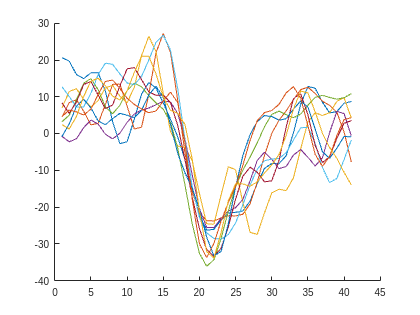

% make sure spikes are lined up
waveforms = []; % dims [spike_num x samples]
figure;
hold on;
for spike_ind = 1:length(spikeTimes_samples)
    t_spike = spikeTimes_samples(spike_ind);
    wf = vtrace(1, t_spike-20:t_spike+20);
    plot(wf);
end
hold off

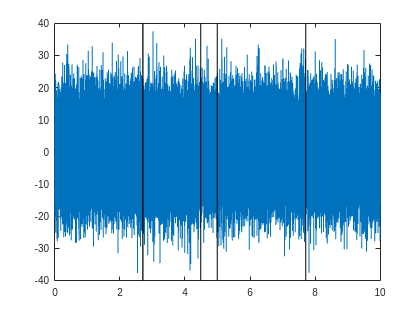

spikeTimes_samples = spikeTimes_samples((spikeTimes_samples >= 1000*30000) & (spikeTimes_samples <= 1010*30000));
figure;
plot(0:(1/30000):10, vtrace(1000*30000:1010*30000));
hold on
for spike_ind = 1:length(spikeTimes_samples)
    t_spike = spikeTimes_samples(spike_ind);
    t_spike_relative = (t_spike - 1000*30000)/30000;
    yl = ylim;
    xl = xlim;
    xBox = [t_spike_relative-(20/30000), t_spike_relative+(20/30000), t_spike_relative+(20/30000), t_spike_relative-(20/30000)];
    yBox = [yl(1), yl(1), yl(2), yl(2)];
    patch(xBox, yBox, 'red', 'FaceAlpha', 0.1);
end
hold off

% Sham example unit + trace
NSx = openNSx('/home/cresp1el-local/Documents/MATLAB/hd_project_sinda/hd_project_sinda/SpikeStuff/Sham/sham_exp1_1/exp1_hd_sham_1709001.ns6', 'read', 'c:29', 'uV', 'precision','double');

% Treated example unit + trace
NSx = openNSx('/home/cresp1el-local/Documents/MATLAB/hd_project_sinda/hd_project_sinda/SpikeStuff/Treated/treated_exp4/exp4_hd_treated_1759001.ns6', 'read', 'c:14', 'uV', 'precision','double');